# Basics of 2D graphics

## Basic line plot

Generate `X` and `Y` vectors and make a line plot of `Y` vs. `X`. The default is to connect the data points with a solid line.

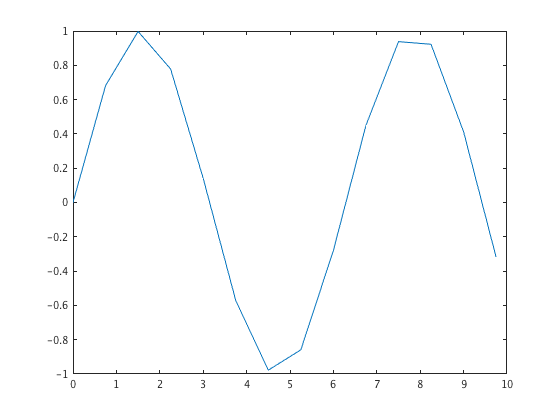

X = 0:0.75:10; Y = sin(X);
plot(X, Y)

The line specifier `-o` plots a solid line with a circle marker at each data point. A grid is also added to the plot.

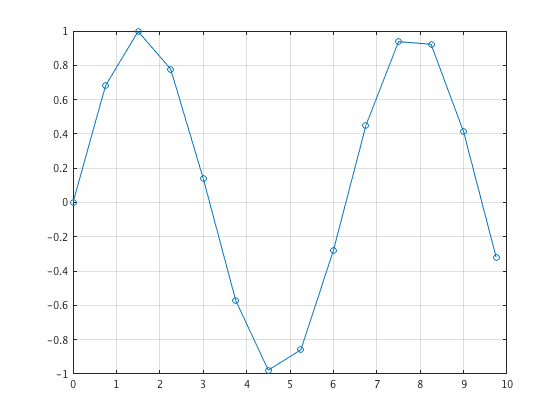

plot(X, Y, '-o')
grid on

Always use the two-argument form  `plot(X, Y)`. If you don't give the `X` vector, MATLAB uses `1...length(Y)` as the x-coordinate, so you lose all information about the `X` values.

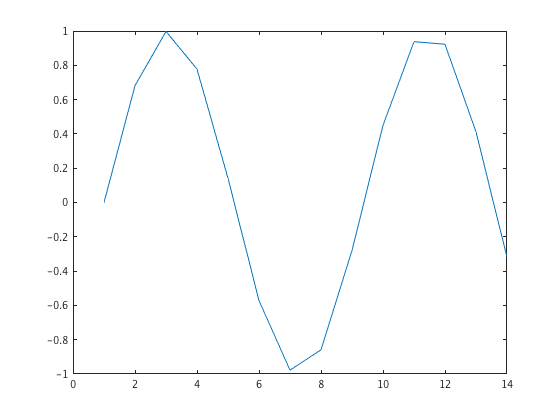

plot(Y)

Increasing the number of data points produces a smoother plot.

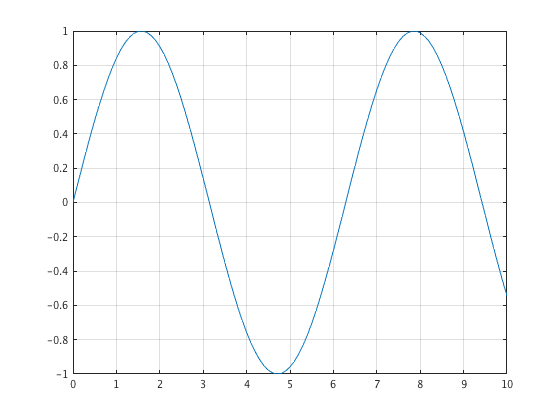

X = 0:0.1:10; Y = sin(X);
plot(X, Y), grid on

## Multiple plots

We can make multiple plots with a single `plot` command. Plot a circle with different color halves. The plot appears elliptical since the axes lengths are different.

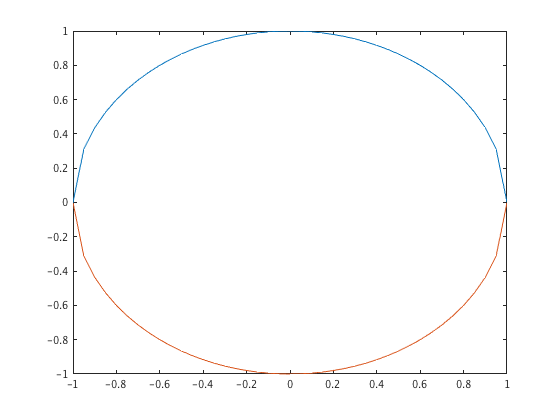

X = -1:0.05:1;
Y1 = sqrt(1 - X.^2);
Y2 = -sqrt(1 - X.^2);
plot(X, Y1, X, Y2)

Make the axes lengths the same.

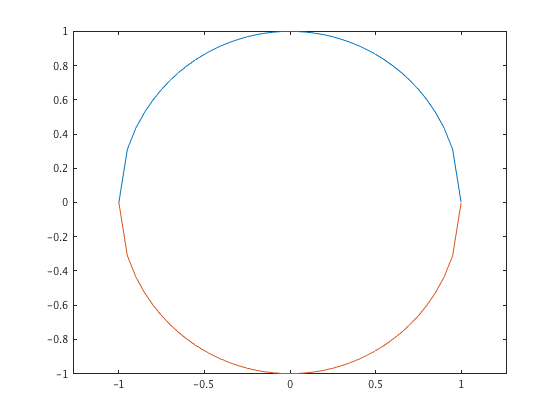

axis equal

The command `axis` sets the axis limits in a figure.

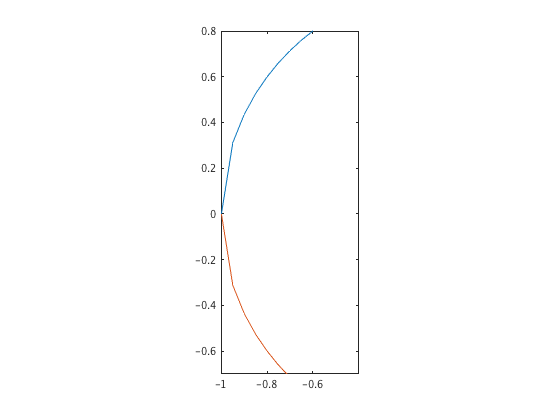

axis([-1 -0.4 -0.7 0.8])

The line specifier `--` produces a dashed line.

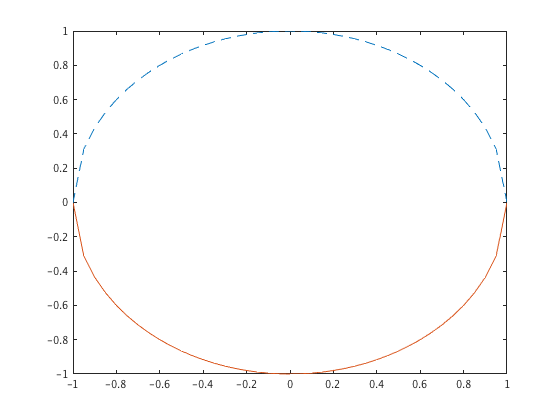

plot(X, Y1, '--', X, Y2)

This also plots `Y1` and `Y2` into the same figure, now with a green dashed line with a square marker at the data points. Using this form you can't use separate line specifications for the graphs.

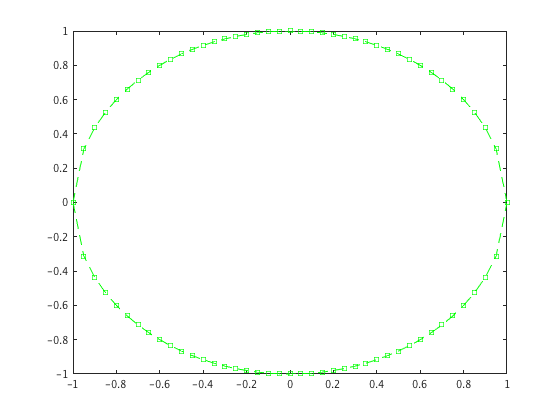

plot(X, [Y1; Y2], 'g--s');

All plots after the `hold on` command are overlaid on the same figure. `hold off` removes the effect of the `hold on` command.

plot(X, Y1), hold on
plot(X, Y2)
hold off

## Labeling plots

The arguments for these self-explanatory commands are strings.

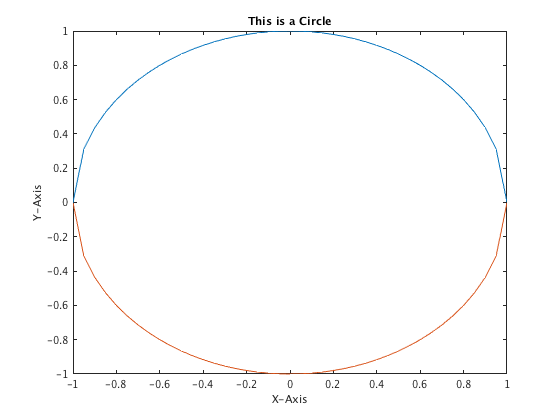

xlabel('X-Axis')
ylabel('Y-Axis')
title('This is a Circle')

The `clf` command clears the figure window. Legend labels are assigned in the same order as the plots were generated.

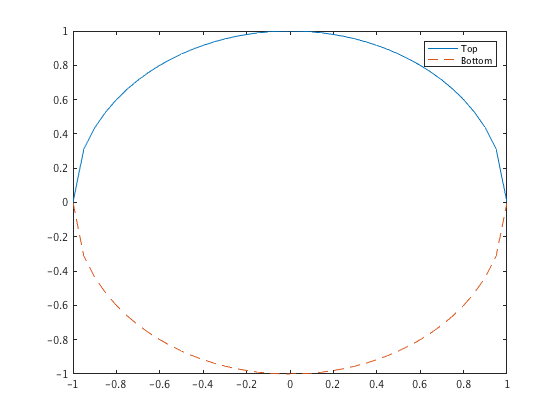

clf
plot(X, Y1, X, Y2, '--')
legend('Top', 'Bottom')

We can change the location of the legend.

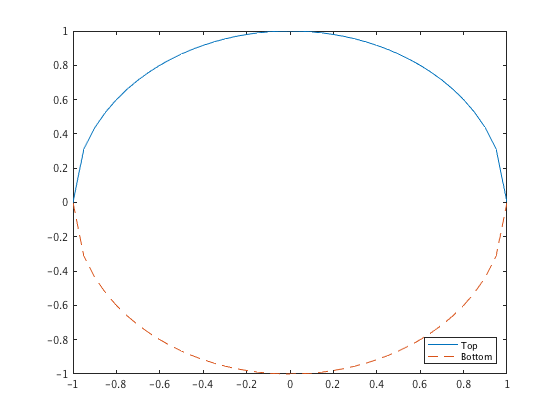

legend('Top', 'Bottom', 'Location', 'SouthEast')

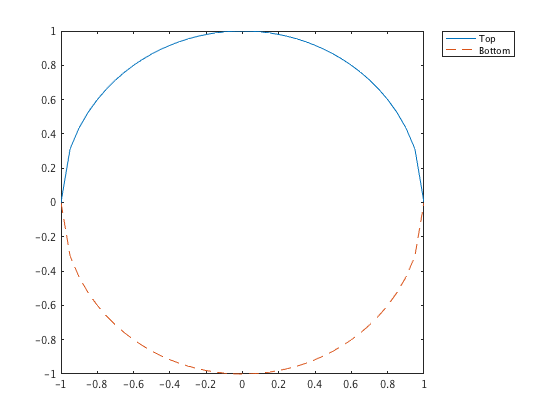

legend('Top', 'Bottom', 'Location', 'NorthEastOutside')

Text strings for labels can include numerical values using `num2str` to convert the values to strings.

r = 1; S = ['r is ', num2str(r)]

S = 'r is 1'

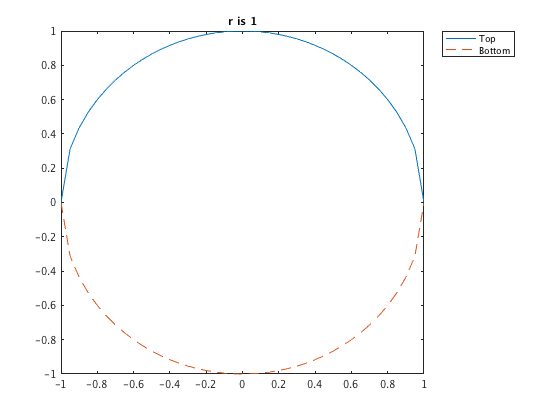

title(S)

You can also use (a limited selection of) TeX commands in labels and title.

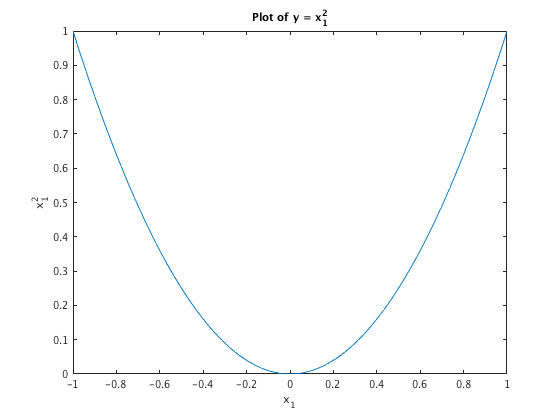

x1 = linspace(-1, 1, 100);
y2 = x1.^2;
plot(x1, y2)
xlabel('x_1')
ylabel('x_1^2')
title('Plot of y = x_1^2')

To get nicer looking text and mathematical symbols, we set the `Interpreter` property to `latex`. Then TeX-commands must be enclosed in dollar-signs.

You can save the plot as a color eps file named `latextext.eps` with the command

`print -depsc latextext`

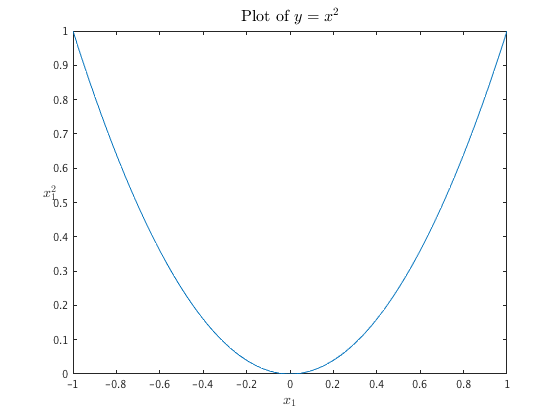

plot(x1, y2)
xlabel('$x_1$', 'Interpreter', 'latex', 'Fontsize', 14)
ylabel('$x_1^2$', 'Interpreter', 'latex', 'Fontsize', 14, 'Rotation', 0)
title('Plot of $y = x^2$', 'Interpreter', 'latex', 'Fontsize', 16)

## Subplots

We can arrange plots into a m x n grid with the `subplot`-command. The subplots are numbered rowwise. Make a 2x2 grid of plots and also illustrate the different line styles available.

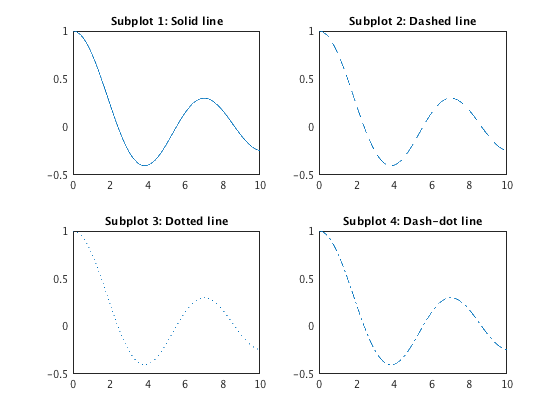

x = 0:0.01:10;
y = besselj(0, x);
subplot(2,2,1), plot(x, y, '-')
title('Subplot 1: Solid line')
subplot(2,2,2), plot(x, y, '--')
title('Subplot 2: Dashed line')
subplot(2,2,3), plot(x, y, ':')
title('Subplot 3: Dotted line')
subplot(2,2,4), plot(x, y, '-.')
title('Subplot 4: Dash-dot line')

A 2x1 grid of plots. Note that we can drop the commas and write `subplot(211)` instead of `subplot(2,1,1)`.

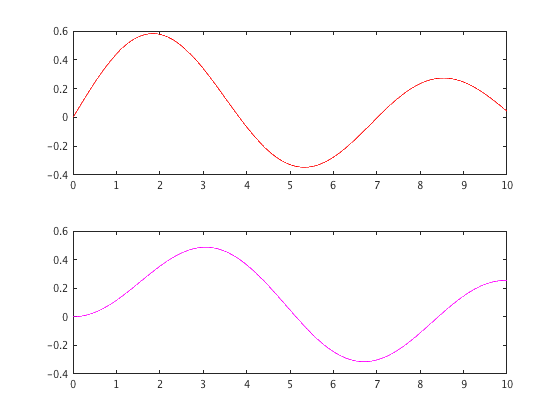

clf
x = 0:0.01:10;
subplot(211), plot(x, besselj(1, x), 'r')
subplot(212), plot(x, besselj(2, x), 'm')

A 1x2 grid of plots.

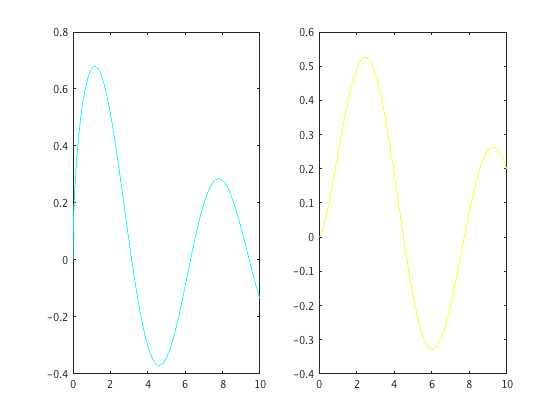

clf
x = 0:0.01:10;
subplot(121), plot(x, besselj(0.5, x), 'c')
subplot(122), plot(x, besselj(1.5, x), 'y')

Subplots can be different sizes. Here the third subplot spans the second row.

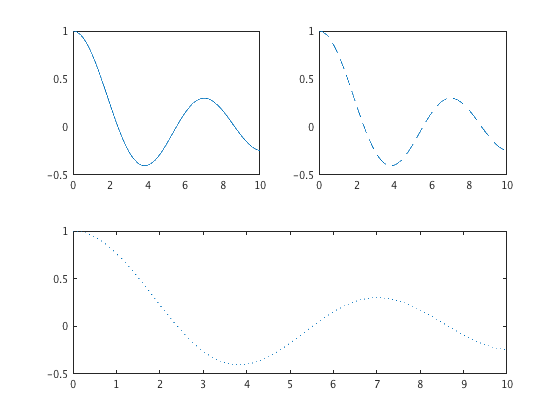

clf
x = 0:0.01:10;
y = besselj(0, x);
subplot(221), plot(x, y, '-')
subplot(222), plot(x, y, '--')
subplot(2,2,[3,4]), plot(x, y, ':')

Here the first plot spans the first column.

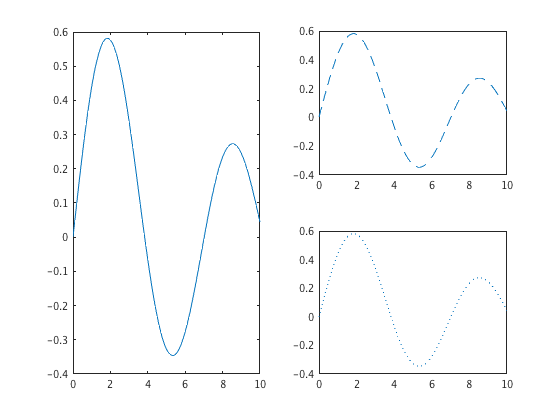

clf
x = 0:0.1:10;
y = besselj(1, x);
subplot(2,2,[1,3]), plot(x, y, '-')
subplot(222), plot(x, y, '--')
subplot(224), plot(x, y, ':')

You can also use the `Position` property of the subplot command. The elements of the position vector are: left, bottom, width, height, and they are normalized between 0.0 and 1.0.

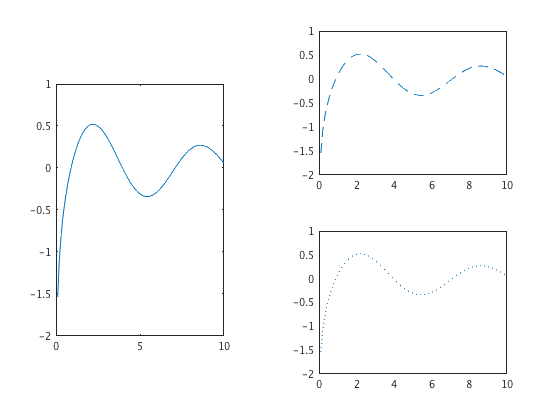

clf
x = 0:0.1:10;
y = bessely(0, x);
subplot('Position', [0.1, 0.2, 0.3, 0.6]), plot(x, y, '-')
subplot(222), plot(x, y, '--')
subplot(224), plot(x, y, ':')

## Other types of plots

Matlab has a large collection of plot types. Here are some of them.

Bar, stem, and stairs plot

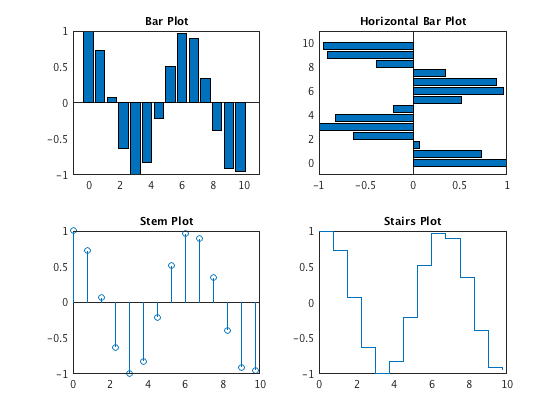

clf
X = 0:0.75:10; Y = cos(X);
subplot(221), bar(X, Y), title('Bar Plot'), xlim([-1, 11])
subplot(222), barh(X, Y), title('Horizontal Bar Plot'), ylim([-1, 11])
subplot(223), stem(X, Y), title('Stem Plot')
subplot(224), stairs(X, Y), title('Stairs Plot')

For a matrix argument of m columns, `bar` plots the data as m groups.

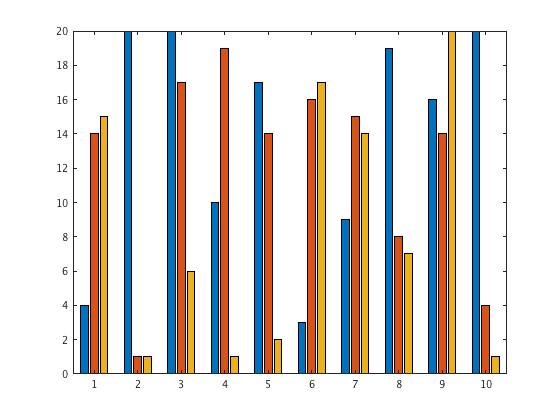

clf
r = randi([1, 20], 10, 3);
bar(r)

The option `'stacked'` stacks the groups vertically.

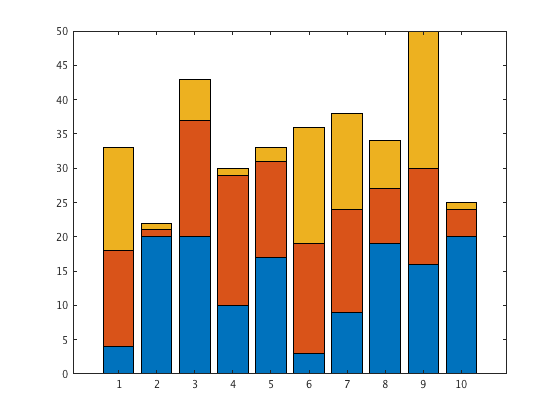

bar(r, 'stacked')

Histogram.

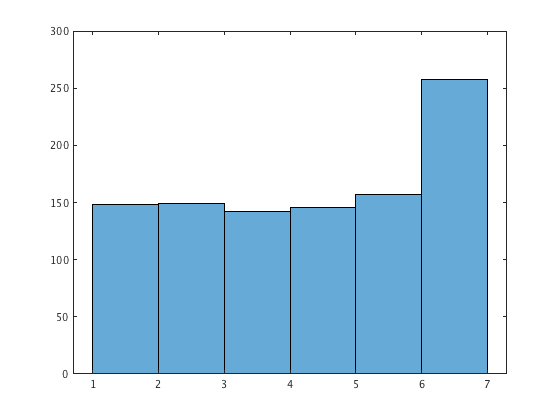

clf
r = randi([1, 7], 1000, 1);
histogram(r, 1:7)

Parametric plot

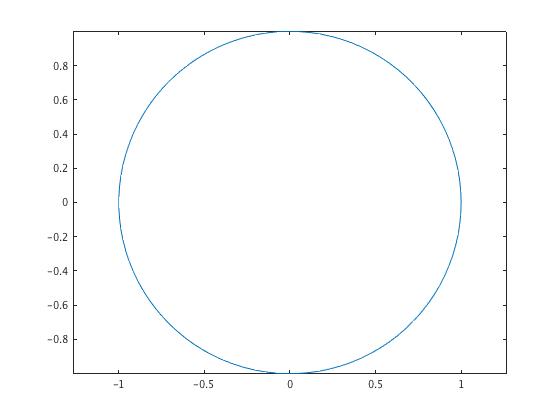

t = linspace(0, 2*pi, 100);
plot(cos(t), sin(t)), axis equal

Polar plot

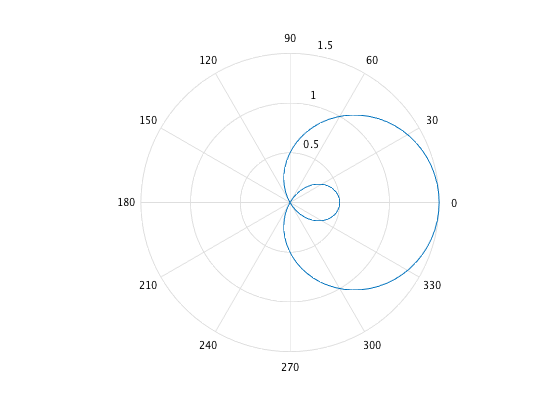

theta = linspace(0, 2*pi, 100);
rho = 0.5*(1 + 2*cos(theta));
polar(theta, rho)

Parametric 3D plot can be done with the command `plot3`.

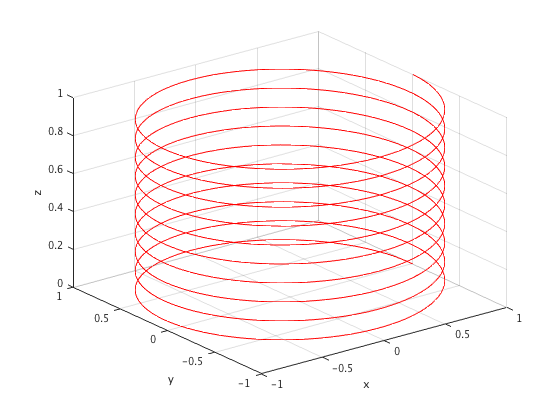

t = linspace(0, 10, 1000);
plot3(cos(2*pi*t), sin(2*pi*t), 0.1*t, 'r')
xlabel('x'), ylabel('y'), zlabel('z'), grid on

Various logarithmic plots. Let us plot the magnitude of type II Chebyshev filter of order 4.

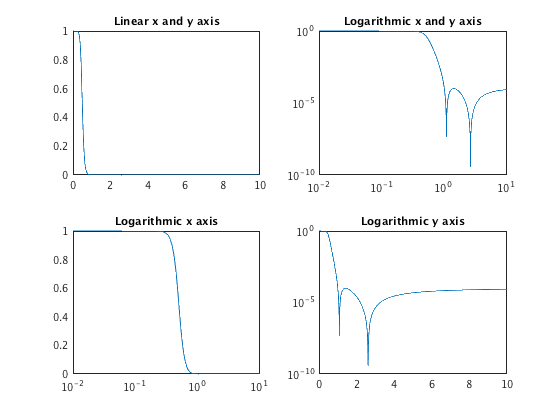

w = 0:0.01:10; ww = 1./w;
T = 8*ww.^4 - 8*ww.^2 + 1;
e = 0.01;
G = 1./(1 + 1./(e^2*T.^2));
subplot(221); plot(w, G);      title('Linear x and y axis')
subplot(222); loglog(w, G);    title('Logarithmic x and y axis')
subplot(223); semilogx(w, G);  title('Logarithmic x axis')
subplot(224); semilogy(w, G);  title('Logarithmic y axis')

## Graphic Objects

Some basic drawing primitives.

A yellow rectangle with the lower left corner at (-7, -0.2), width 2.5 and height 4.

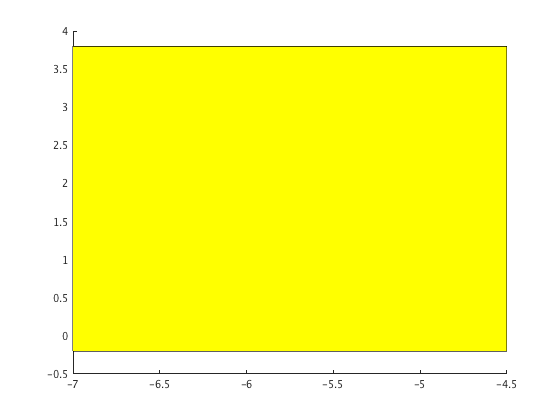

clf
rectangle('Position', [-7 -0.2 2.5 4], 'FaceColor', 'y')

A red line of width 2 between the points (-2, -0.4), (1, 3), (-4, 2), and (-4, -0.6). Note that it is added to the axes without erasing the previous contents. The first and second arguments are a vector of x- and y-coordinates, respectively.

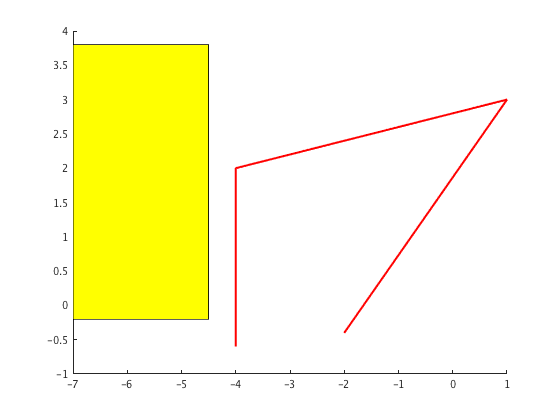

line([-2 1 -4 -4], [-0.4 3 2 -0.6], 'Color', 'r', 'LineWidth', 2);

Polygons can be made with the `patch` command. In the second patch command below, the last argument is a color specification that sets the face color to blue.

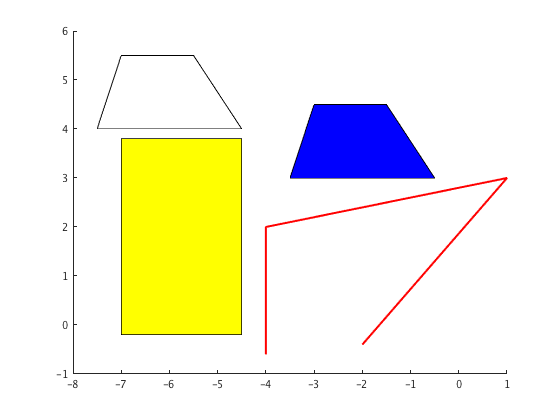

xdata = [-7, -5.5, -4.5, -7.5];
ydata = [5.5, 5.5, 4, 4];
patch('XData', xdata, 'YData', ydata, 'FaceColor', 'none')
patch(xdata + 4, ydata - 1, 'b')

Text can be added with the `text` command.

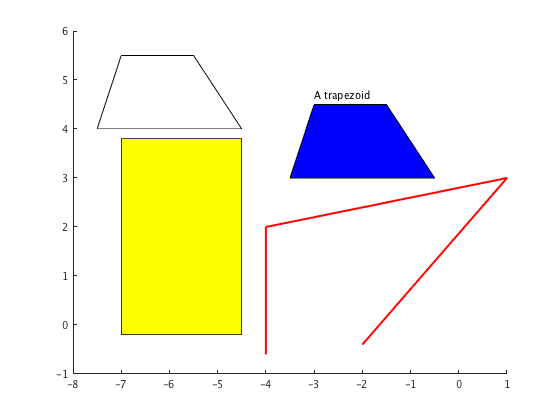

text(-3, 4.7, 'A trapezoid')

Rectangles can have rounded corners. The curvatures must be in the interval `[0, 1]`. Setting the curvature to 1 gives an ellipse or a circle.

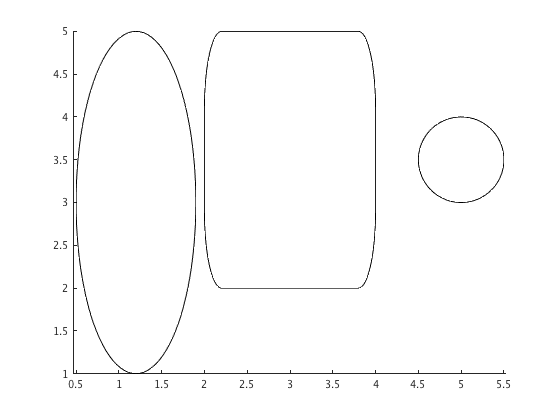

clf
rectangle('Position', [2 2 2 3], 'Curvature', [0.2, 0.6])
rectangle('Position', [0.5 1 1.4 4], 'Curvature', [1 1]) % An ellipse
rectangle('Position', [4.5 3 1 1], 'Curvature', [1 1])   % A circle
axis equal

Let's make an anonymous function that draws a circle and takes optional arguments to set the properties of the circle.

circle = @(c, r, varargin) rectangle('Position', [c(1)-r c(2)-r 2*r 2*r],...
    'Curvature', [1 1], varargin{:})

circle = function_handle with value:
    @(c,r,varargin)rectangle('Position',[c(1)-r,c(2)-r,2*r,2*r],'Curvature',[1,1],varargin{:})


Now we draw some circles.

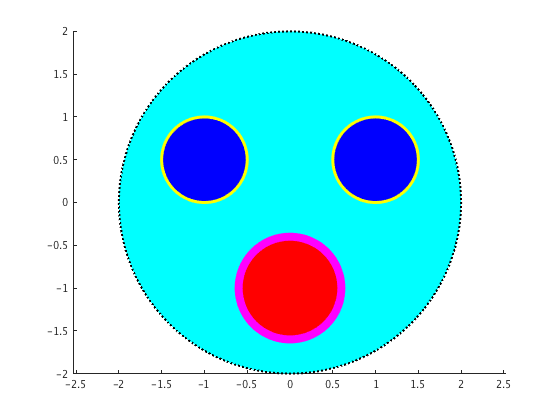

clf
circle([0 0], 2, 'FaceColor', 'c', 'LineWidth', 2, 'LineStyle', ':')
circle([-1 0.5], 0.5, 'FaceColor', 'blue', 'EdgeColor', 'y', 'LineWidth', 3)
circle([1 0.5], 0.5, 'FaceColor', 'blue', 'EdgeColor', 'y', 'LineWidth', 3)
circle([0 -1], 0.6, 'FaceColor', 'r', 'EdgeColor', 'm', 'LineWidth', 8)
axis equal

## Handle Graphics

A graphics object can be manipulated through a *handle*, which is a reference to the object. A graphics object can be treated as a struct whose fields give the properties of the object.

The plot command returns a handle to the plot.

h =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×629 double]
              YData: [1×629 double]
              ZData: [1×0 double]

  Show all properties


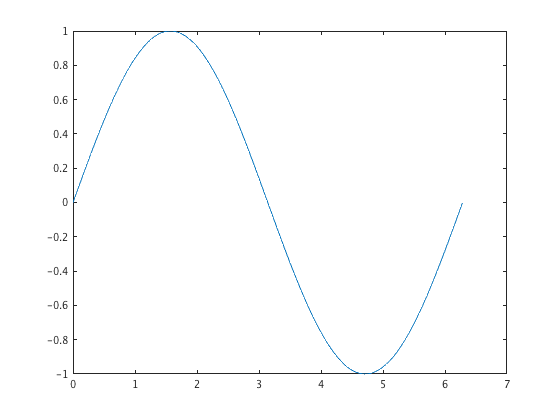

x = 0:0.01:2*pi; y = sin(x);
h = plot(x, y)

The command `get` shows the all the properties of a graphics object.

get(h)

    AlignVertexCenters: 'off'
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: 'off'
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: 'on'
                 Color: [0 0.4470 0.7410]
             CreateFcn: ''
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: 'on'
         Interruptible: 'on'
              LineJoin: 'round'
             LineStyle: '-'
             LineWidth: 0.5000
                Marker: 'none'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1×629 uint64]
            MarkerSize: 6
                Parent: [1×1 Axes]
         PickableParts: 'visible'
              Selected: 'off'
    SelectionHighlight: 'on'
                   Tag: ''
                  Type: 'line'
         UIContextMenu: [0×0 GraphicsPlaceholder]
              UserData: []
             

You can set and get the properties with the dot-notation.

h.LineStyle

ans = '-'

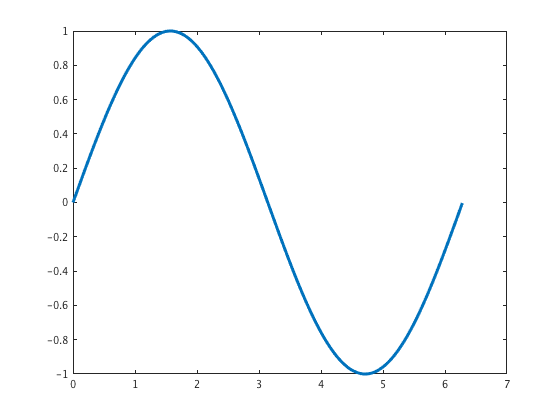

h.LineWidth = 3;

You can also use the `get` and `set` commands, although the dot-notation is preferred. The command `get(h, 'PropertyName')` returns the value of the property `PropertyName`.

get(h, 'LineStyle')

ans = '-'

The command `set` changes the properties of an object. The first argument is a handle to the object. The `set` command is useful if we want to change several properties at the same time. Here the line color is given as an RGB vector.

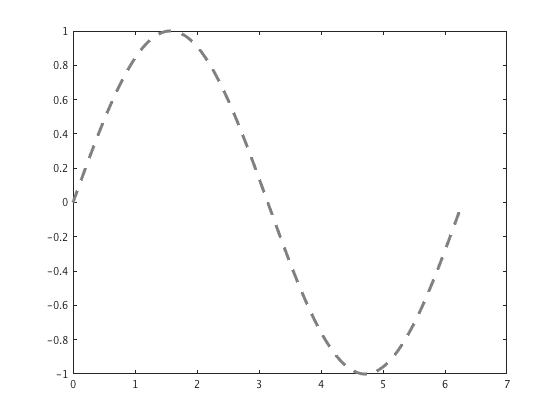

set(h, 'Color', [0.5 0.5 0.5], 'LineStyle', '--')

The command `set(h, 'PropertyName')` shows the possible values of property `PropertyName`. The default value is shown in braces.

set(h, 'LineStyle')

  5×1 cell array

    {'-'   }
    {'--'  }
    {':'   }
    {'-.'  }
    {'none'}



The properties `XData` and `YData` hold the x- and y-coordinates of the plot. Here we sneakily change the plot of sine to the plot of cosine by changing the `YData` property.

h =   Line with properties:

              Color: [0.5000 0.5000 0.5000]
          LineStyle: '--'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×629 double]
              YData: [1×629 double]
              ZData: [1×0 double]

  Show all properties


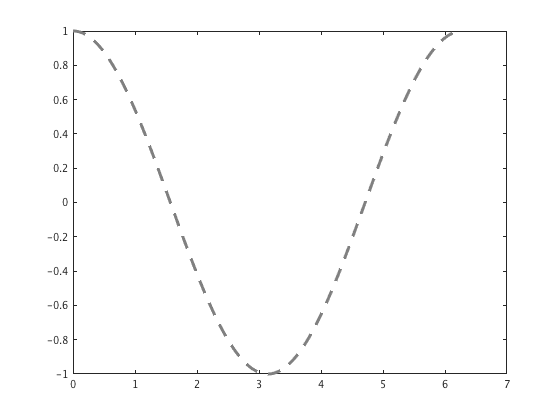

x = h.XData;
h.YData = cos(x)

For more than one plot in a figure, `plot` returns a vector of handles, a handle for each plot.

x = 0:0.25:4*pi;
h = plot(x, sin(x), x, cos(x))

h =   2×1 Line array:

  Line
  Line


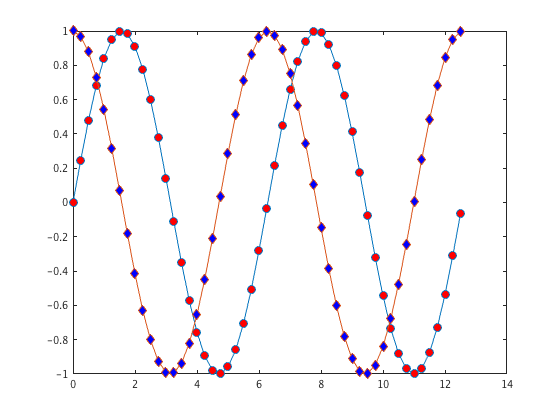

set(h(1), 'Marker', 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 8)
set(h(2), 'Marker', 'd', 'MarkerFaceColor', 'b', 'MarkerSize', 8)

We could have set the properties with a single command.

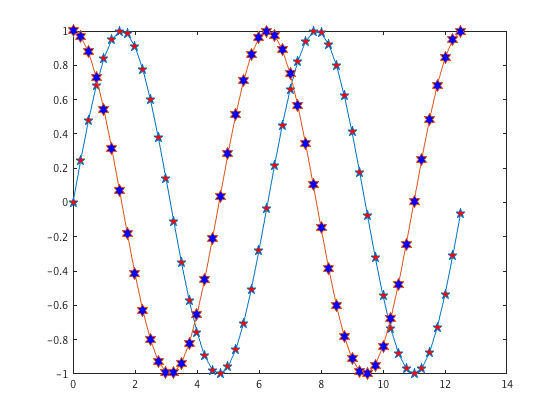

set(h, {'Marker', 'MarkerSize'}, {'p', 10; 'h', 12})

The command `gca` (get handle to current axis) returns a handle to the current axis. This gives the limits of the y-axis.

get(gca, 'YLim')

ans =     -1     1


All the properties of the current axis.

                       ALim: [0 1]
                   ALimMode: 'auto'
     ActivePositionProperty: 'outerposition'
          AmbientLightColor: [1 1 1]
               BeingDeleted: 'off'
                        Box: 'on'
                   BoxStyle: 'back'
                 BusyAction: 'queue'
              ButtonDownFcn: ''
                       CLim: [0 1]
                   CLimMode: 'auto'
             CameraPosition: [7 0 17.3205]
         CameraPositionMode: 'auto'
               CameraTarget: [7 0 0]
           CameraTargetMode: 'auto'
             CameraUpVector: [0 1 0]
         CameraUpVectorMode: 'auto'
            CameraViewAngle: 6.6086
        CameraViewAngleMode: 'auto'
                   Children: [2×1 Line]
                   Clipping: 'on'
              ClippingStyle: '3dbox'
                      Color: [1 1 1]
                 ColorOrder: [7×3 double]
            ColorOrderIndex: 3
                  CreateFcn: ''
               CurrentPoint: [2×3 double]
          

get(gca)

Set tick marks on the x-axis at multiples of $\pi/2$ and set the corresponding tick labels as TeX strings. Notice that the strings are given as a cell array.

hax = gca

hax =   Axes with properties:

             XLim: [0 14]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


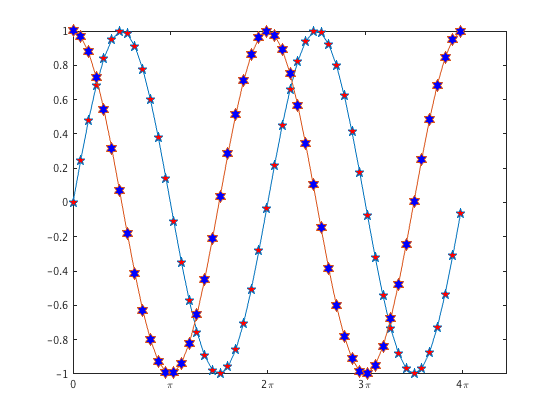

hax.XTick = (0:4)*pi;
hax.XTickLabel = {'0', '\pi', '2\pi', '3\pi', '4\pi'};

The command `gcf` (get handle to current figure) returns a handle to the current figure.

get(gcf, 'PaperUnits')

ans = 'centimeters'

All the properties of the current figure.

get(gcf)

                 Alphamap: [1×64 double]
             BeingDeleted: 'off'
               BusyAction: 'queue'
            ButtonDownFcn: ''
                 Children: [1×1 Axes]
                 Clipping: 'on'
          CloseRequestFcn: 'closereq'
                    Color: [0.9400 0.9400 0.9400]
                 Colormap: [64×3 double]
                CreateFcn: ''
              CurrentAxes: [1×1 Axes]
         CurrentCharacter: ''
            CurrentObject: [0×0 GraphicsPlaceholder]
             CurrentPoint: [0 0]
                DeleteFcn: ''
             DockControls: 'on'
                 FileName: ''
        GraphicsSmoothing: 'on'
         HandleVisibility: 'on'
            InnerPosition: [680 678 560 420]
            IntegerHandle: 'on'
            Interruptible: 'on'
           InvertHardcopy: 'on'
              KeyPressFcn: ''
            KeyReleaseFcn: ''
                  MenuBar: 'none'
                     Name: 'Figure'
                 NextPlot: 'add'
                  

## Adding User Interface Elements to a Figure

Due to current limitations of the Live Editor we have to open a separate window for the UI elements to work. They don't work in the figures embedded in the Live Script.

hf = figure('Visible', 'on')

hf =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


We make a plot an set its `ButtonDownFcn` property to the **callback function** `toggleMarker` (at the end of the file). Then clicking on the plot toggles between showing the markers and hiding them.

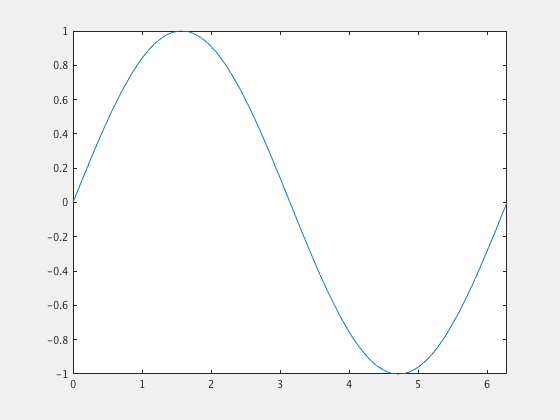

fplot(@sin, [0 2*pi], 'ButtonDownFcn', @toggleMarker)

Get a handle to the current axes.

ha = gca;

Next we set the `ButtonDownFcn` property of the axes object to a callback function that sets the background color of the axes to a random color (given as an RGB triplet) everytime the user clicks inside the axes area. Clicking in the figure outside the axes has no effect.

Notice that clicking on the plot toggles the marker but doesn't change the background color.

ha.ButtonDownFcn = @(h, ~) set(h, 'Color', rand(1, 3));

Next we make a Context Menu and assign to a plot. Then right-clicking the plot opens a context menu that allows the user to increase or decrease the line width.

The callback functions `thicker` and `thinner` are usually called with two arguments, which we don't need in this case. The syntax` {@thicker, 3}` allows us to pass the third argument `incr`, which is the amount to increase the width. For `thinner` we show an alternative way of passing extra arguments using an anonymous function.

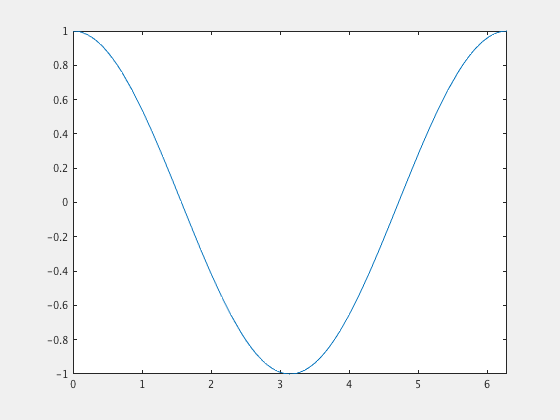

clf(hf)
cmh = uicontextmenu;
uimenu(cmh,'Text', 'Thicker', 'MenuSelectedFcn', {@thicker, 3});
uimenu(cmh,'Text', 'Thinner', 'MenuSelectedFcn',...
    @(src, evt) thinner(src, evt, 1));
fplot(@cos, [0 2*pi], 'UIContextMenu', cmh)

function toggleMarker(hObj, ~) % We don't need the second argument
    % Callback function for ButtonDownFcn that toggles the marker on/off
    
    if strcmpi(hObj.Marker, 'none')
        hObj.Marker = 'o';
    else
        hObj.Marker = 'none';
    end
end

function thicker(~, ~, incr) % We don't need the first two arguments
    % Callback function for the uimenu "Thicker"
    
    h = gco; % Get the current object
    h.LineWidth = h.LineWidth + incr;
end

function thinner(~, ~, decr) % We don't need the first two arguments
    % Callback function for the uimenu "Thinner"
    
    h = gco; % Get the current object
    w = h.LineWidth - decr;
    if w > 0
        h.LineWidth = w;
    end
end